# Figure 11, lg_ta_PRV

The code below allows to plot pooled GS and TA from PRV experimetns

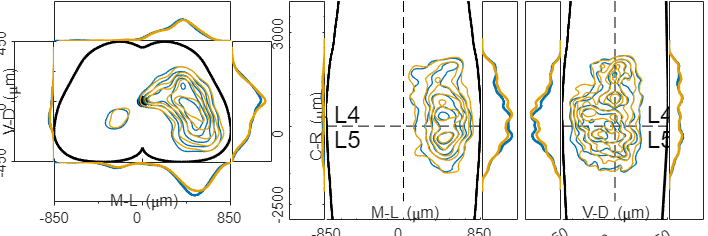

masterdir = 'F:\documents\master\data\';
clearvars -except masterdir
ExpTypeString = {'chat', 'olig2','aav_wt',...
    'aav_chat','prv'};
MuscleType = {'lg','mg','gs','ta','pl'};
MuscleTypeSecond = {'nil', 'lg','mg','gs','ta','pl'};
ext = 'xlsx';
ExpType = {'prv'}; 
firstmuscle = {'gs'};
secondmuscle = {'ta'};
%titer = 'high'; % can be 'high' or 'low'
concat = 1;
% Defines folders for each muscles and number of muscles

firstmuscledir = [masterdir,firstmuscle{1},'_',ExpType{1},'\'];
if ~isfolder(firstmuscledir)
    disp ('Please pick another first muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all other experiments')
    firstfiles = [];
    return
else
    firstfiles = dir([firstmuscledir,'*.',ext]);
end

yes_second = ~contains(secondmuscle,'nil');

if yes_second
    secondmuscledir = [masterdir,secondmuscle{1},'_',ExpType{1},'\'];
    if ~isfolder(secondmuscledir)
        disp ('Please pick another second muscle: LG, MG and PL were injected only for experiments on ChAT-PhiGT, GS and TA were injected in all 9other experiments')
        secondfiles = [];
        return
    else
        secondfiles = dir([secondmuscledir,'*.',ext]);
    end
else
end

% [fnfirst,pathfirst] =  uigetfile([firstmuscledir,'*.xlsx'],'Select One or more files for first muscle', ...
%            'MultiSelect', 'on');
 fnfirst = {firstfiles(:).name}; %picks all files from first directory
 pathfirst = firstmuscledir;

if yes_second
%     [fnsecond,pathsecond] =  uigetfile([secondmuscledir,'*.xlsx'],'Select One or more files for second muscle', ...
%             'MultiSelect', 'on');    
    fnsecond = {secondfiles(:).name}; %picks all files from second directory
    pathsecond = secondmuscledir;
    nfiles_ = [length(string(fnfirst)), length(string(fnsecond))];
    dn = {pathfirst,pathsecond};
else   
    nfiles_ = length(string(fnfirst)); %here and above: string must be used to accommodate for single files
    dn = {pathfirst};
end
ndir = length(dn);

% declares all cell and matrix variables
ins = cell(1,ndir);
mns = cell(1,ndir);
gckin = cell(1,ndir);
gckmn = cell(1,ndir);
gckinxz = cell(1,ndir);
gckmnxz = cell(1,ndir);
gckinyz = cell(1,ndir);
gckmnyz = cell(1,ndir);

nfiles = [];
ptpeak = [];
prpeak = [];
plpeak = [];
pbpeak = [];
peakcontraxz = [];
peakipsixz = [];
peakcontrayz = [];
peakipsiyz = [];

% First index is the directory, second is file the extra i is to
% accommodate for choice of single files in order to keep the string format

if nfiles_(1)==1
    ins_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',1);
    mns_{1}{1} = readmatrix([dn{1},fnfirst], 'Sheet',2);
else
    for j = 1:nfiles_(1)
        ins_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',1);
        mns_{1}{j} = readmatrix([dn{1},fnfirst{j}], 'Sheet',2);
    end
end

if size(nfiles_,2)==2
    if nfiles_(2) ==1
        ins_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',1);
        mns_{2}{1} = readmatrix([dn{2},fnsecond], 'Sheet',2);
    else
        for j = 1:nfiles_(2)
            ins_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',1);
            mns_{2}{j} = readmatrix([dn{2},fnsecond{j}], 'Sheet',2);
        end
    end
else
end



if concat == 1
    for  i = 1:ndir
        % the extra {1} is to make it compatible with codes using
        % two indexes if files are not concatenated
        ins{i}{1} = vertcat(ins_{i}{:});
        mns{i}{1} = vertcat(mns_{i}{:});
    end
else
    for i = 1:ndir
        for j = 1:nfiles_(i)
            ins{i}{j} = ins_{i}{j};
            mns{i}{j} = mns_{i}{j};
        end
    end
end

% rewrite nfiles after concatenation
for i = 1:ndir
    nfiles(i) = size(ins{i},2);
end

%[ins,mns] = poolfun(dn,concat); % ins and mns have the same dimensions 

MNON = true; MNONPROJ = false;
qq = 6;
dotson = 0;
contlevlong = 5;
contlevtrans = 5;

% figure settings
autoscale = 1; % Set autoscale on Y axis of interneurons densities
ker = [5,5];          % kernel size
res = [100,100];         % kernel resolution

nr1 = 3;               % Number of rows in panel grid
nc1 = 9;               % Number of columns in panel grid
sizex1 = 15;           % Absolute width of figure (in cm)
sizey1 = 5;            % Absolute height of figure (in cm)         
margx = 0.1;           % x-margin between and around panels (normalised units)
margy = 0.1;           % y-margin between and around panels (normalised units)
labelalign = 'sw';     % NESW alignment of labels
labelfsize = 18;       % Label font size
% contlevlong = 5;       % contour levels for xz and yz plots
% contlevtrans = 5;      % contour levels for transverse slice
inmarkersize=2;        % size of Mn marker
mnmarkersize=5;        % size of Mn marker
mnlw = 0.01;            % width of Mn edge marker
contlw =1;             % line width for contours
lwconv = 2;            % line width of convolution plots

% loads tab files with sc profiles
scp = readmatrix('halfcordt.txt'); %transverse
scf = readmatrix('halfcordf.txt');  % frontal
sclv = readmatrix('halfcordf.txt');  % lateral ventral, same as frontal
scld = readmatrix('halfcordld.txt');  % lateral dorsal

if  isempty(mns)
    mns = [0,0,0];
    mnmarkersize=0;
    mnlw = 0;
end

   xl = [-.5,.5]; 
   yl = [-0.5,0.5];

    zl = [-4000,3000];
    plim = [0,0.01]; % these settings are overridden if autoscale is on
    plimz = [0,2e-5];
    plimlong = [0,0.23];
    
% color matrix: creates a matrix of colours scaling the primary colors to
% darker shades for increasing n of experiment. First index is directory,
% second is file

first = [0, 114, 178]/255; %{0, 0.4471, 0.6980}  %blu = 1st directory LG
firstdark = [0, 114, 178]/450; %{0, 0.2533, 0.3956} %dark blu = 2nd directory = MG
second = [230, 159, 0]/255;  %{0.9020, 0.6235,0} orange = TA inhibitory
seconddark = [180/255, 100/255, 0]; %{0.7059, 0.3922, 0} dark orange = TA excitatory
third = [0,0,1];

switch string(firstmuscle)
    case 'lg'
        primarycols{1} = first;
    case 'mg'
        primarycols{1} = firstdark;
    case 'gs'
        primarycols{1} = first;
    case 'ta'
        primarycols{1} = second;
    case 'pl'
        primarycols{1} = seconddark;
end

if yes_second
    switch string(secondmuscle)
        case 'lg'
            primarycols{2} = first
        case 'mg'
            primarycols{2} = firstdark;
        case 'gs'
            primarycols{2} = first;
        case 'ta'
            primarycols{2} = second;
        case 'pl'
            primarycols{2} = seconddark;
    end
else
    primarycols{2} = second;
end
primarycols{3} = third;

%primarycols = {first,second,third}; % standard list, GS=green, TA=red
scalecol = cell(1,ndir);
cols = cell(1,ndir);

for i = 1:ndir
   
    if nfiles(i) == 1
        scalecol{i} = 1;
    else
        scalecol{i} = linspace(1,0.5,nfiles(i));
    end
    
    for j = 1:nfiles(i)
    cols{i}{j} = primarycols{i}*scalecol{i}(j);

    end
end

for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j} = gckernel();
        gckmn{i}{j} = gckernel();
        gckinxz{i}{j} = gckernel();
        gckmnxz{i}{j} = gckernel();
        gckinyz{i}{j} = gckernel();
        gckmnyz{i}{j} = gckernel();
      
    end
end
  
for i = 1:ndir
    for j = 1:nfiles(i)
        gckin{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,2)'], [std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckin{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,2)']);
        %nomn = ~isempty(mns{i}{j}); %REPLACE NOMN WITH size(mns{i}{j}) for cases with 1 Mn only
        nmn = size(mns{i}{j},1);
        if nmn>1
            gckmn{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,2)']);
            gckmnxz{i}{j}.convolve([mns{i}{j}(:,1)'; mns{i}{j}(:,3)']);
        else
            
        end
        setKernel(gckin{i}{j},ker);
        setResd(gckin{i}{j},res);
        setKernel(gckinxz{i}{j},ker);
        setResd(gckinxz{i}{j},res);
        setKernel(gckinyz{i}{j},ker);
        setResd(gckinyz{i}{j},res);
        gckinxz{i}{j}.setData([ins{i}{j}(:,1)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinyz{i}{j}.setData([ins{i}{j}(:,2)'; ins{i}{j}(:,3)'],[std(ins{i}{j}(:,1))/qq,std(ins{i}{j}(:,1))/qq]);
        gckinxz{i}{j}.convolve([ins{i}{j}(:,1)'; ins{i}{j}(:,3)']);
        gckinyz{i}{j}.convolve([ins{i}{j}(:,2)'; ins{i}{j}(:,3)']);
        
    end
end

% OUTPUT FIGURE 1
f1 = figure;
%set(f1,'Position',[10 10 f1.Position(3) f1.Position(4)]);
set(f1,'Position',[10 10 1500 500]);
h = 0;
% aa = annotation('line', [0.14,0.25],[0.05,0.05]);
% aa.LineWidth = lwconv;
% annotation('textbox', [0.165,0.11,0.05,0.03],'String','1 mm','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('doublearrow', [0.805,0.935],[0.05,0.05]);
% annotation('textbox', [0.815,0.1,0.03,0.03],'String','V','LineStyle','none','FontSize',15,'FitBoxToText','on');
% annotation('textbox', [0.895,0.1,0.03,0.03],'String','D','LineStyle','none','FontSize',15,'FitBoxToText','on');
Panels = panels([nr1, nc1], [sizex1, sizey1], 1, [margx, margy]); % Initialise panel class instance
Panels.setLabels(Panels.lbl, labelalign, labelfsize);  

Panels.tweak(2,[-0.4,0.42],[2.5,0.5682]);
Panels.tweak(20,[-0.4,0.37],[2.5,0.5682]);
Panels.tweak(10,[0.14,-0.17],[0.5682,1.7]);
Panels.tweak(12,[1.0,-0.17],[0.5682,1.7]);
Panels.tweak(11,[-0.4,-0.17],[2.5,1.7]);
Panels.tweak(14,[0.1,-1.],[2.2,3.1]);
Panels.tweak(13,[0.7,-1.],[0.5,3.1]);
Panels.tweak(15,[1.2,-1.],[0.5,3.1]);
Panels.tweak(17,[0.1,-1.0],[1.5,3.1]);
Panels.tweak(16,[0.7,-1.0],[0.5,3.1]);
Panels.tweak(18,[0.5,-1.0],[0.5,3.1]);


h = 11;
dotxy = Panels.setPanel(h);
cc = plot (0,0,'ko');
    set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
    hold on
plot(2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scp(:,1),2*yl(2)*scp(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         
         if dotson
             inpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,2),'.','MarkerEdgeColor',...
                 cols{i}{j},'MarkerSize',inmarkersize);
         else
             [MM,contu] = contour(x,y,P,contlevtrans);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
         
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,2),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
             
         end
            ax = gca;
         set (ax, 'xlim',xl, 'ylim',yl,'Visible','off','XTick',[],'YTick',[])
 box off
    end
 end

h = 2;
top = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pt = sum( P(y>=0,:),1);
         ptpeak(i,j) = max(max(pt));
         topplot = plot(x,pt);
         %sum(pt)
         hold on
         set(topplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'XTick',[],'YTick',[])         
 
    end
end

h = 12;
right = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pr = sum( P(:,x>=0),2);
         prpeak(i,j) = max(max(pr));
         rightplot = plot(pr,y);
         hold on
         if MNONPROJ
             xmn = gckmn{i}{j}.x;
             ymn = gckmn{i}{j}.y;
             Pmn = gckmn{i}{j}.P;
             prmn = sum( Pmn(:,:),2);
             rightplotmn = plot(prmn,ymn);
             set(rightplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         set(rightplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim',plim,'ylim', yl,'XTick',[],'YTick',[])   ;     

    end
end

h = 10;
left = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pl = sum( P(:,x<0),2);
         plpeak(i,j) = max(max(pl));
         leftplot = plot(pl,y);
         hold on
         set(leftplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'ylim', yl,'xlim',plim,'xdir','reverse','XTick',[],...
             'YTick',[-0.5,0, 0.5],'YTickLabel',[-450,0,450],'YTickLabelRotation',90,...
         'TickLabelInterpreter','tex')   ;
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'V-D (\mum)';
         ax.YLabel.Position = [0.0065 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';
         ax.YAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.YAxis.TickDirection = 'out';
         ax.YAxis.TickLength = [0.0200 0.0250];
    end
end

h = 20;
bot = Panels.setPanel(h);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckin{i}{j}.x;
         y = gckin{i}{j}.y;
         P = gckin{i}{j}.P;
         pb = sum( P(y<0,:),1);
         pbpeak(i,j) = max(max(pb));
         botplot = plot(x,pb);
         %sum(pb)
         hold on
        
         if MNONPROJ
             x = gckmn{i}{j}.x;
             y = gckmn{i}{j}.y;
             P = gckmn{i}{j}.P;
             pb = sum( P(:,:),1);
             botplotmn = plot(x,pb);
             set(botplotmn,'color',cols{i}{j}, 'LineStyle',':','LineWidth',lwconv);
         else
         end
         
         set(botplot,'color',cols{i}{j}, 'LineWidth',lwconv);
         ax = gca;
         set(ax,'xlim', xl,'ylim',plim,'ydir','reverse',...
             'XTick',[-0.5,0, 0.5],'XTickLabel',[-850,0,850],'YTick',[])   ; 
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 0.006];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
         ax.XAxis.MinorTickValues = [-0.5,-0.25,0,0.25,0.5]; 
         ax.XAxis.TickDirection = 'out';
         ax.XAxis.TickLength = [0.0200 0.0250];

    end
end

% longitudinal xz

h = 13;
 contraxz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pcontraxz = sum( P(:,x<0),2);
         plotcontra = plot(pcontraxz,y);
         peakcontraxz(i,j) = max(max(pcontraxz));
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse',...
             'XTick',[],'YTick',[-3000,0,2500],'YTickLabel',[3000,0,-2500],...
             'YTickLabelRotation',90)
         set(ax.YLabel,'Interpreter','tex');
         ax.YLabel.String = 'C-R (\mum)';
          ax.YLabel.Position = [-0.0015 4.7684e-07];
%         ax.YLabel.Position = [0.13 4.7684e-07];
         ax.YAxis.FontSize = 11;
         ax.YAxis.FontName = 'arial';
         ax.YAxis.MinorTick = 'on';

    end
 end
 
 
h=14;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %right halfcord
plot(-2*xl(2)*scf(:,1),-2*zl(2)*scf(:,2),'LineWidth',lwconv,'Color','k'); %left halfcord 
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.9*xl(1),400,'L5', 'FontSize', 18);
        text(0.9*xl(1),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,1),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,1),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-850,0,850],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'M-L (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 15;
 ipsixz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)  
         x = gckinxz{i}{j}.x;
         y = gckinxz{i}{j}.y;
         P = gckinxz{i}{j}.P;
         pipsixz = sum( P(:,x>=0),2);
         peakipsixz(i,j) = max(max(pipsixz));         
         plotipsi = plot(pipsixz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

% longitudinal yz

h = 16;
 contrayz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pcontrayz = sum( P(:,x<0),2);
         peakcontrayz(i,j) = max(max(pcontrayz));
         plotcontra = plot(pcontrayz,y);
         hold on
         set (plotcontra,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'xdir','reverse','ydir','reverse','XTick',[],'YTick',[])

    end
 end
 
 
h=17;
dotxz = Panels.setPanel(h);
cc = plot ([0,0],[zl(1),0.8*zl(2)],'k','LineStyle','--');
        set(cc,'MarkerFaceColor',[0,0,0],'MarkerSize',8)
        hold on
plot(-2*yl(2)*sclv(:,1),-2*zl(2)*sclv(:,2),'LineWidth',lwconv,'Color','k'); %ventral halfcord
plot(2*yl(2)*scld(:,1),-2*zl(2)*scld(:,2),'LineWidth',lwconv,'Color','k'); %dorsal halfcord
plot(xl,[0,0],'k','LineStyle','--') 
        text(0.6*yl(2),400,'L5', 'FontSize', 18);
        text(0.6*yl(2),-400,'L4', 'FontSize', 18);
for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         if dotson
             dotpl = plot(ins{i}{j}(:,2),ins{i}{j}(:,3),'.','MarkerSize',inmarkersize,...
                 'MarkerEdgeColor',cols{i}{j});
         else
             [MM,contu] = contour(x,y,P,contlevlong);
             set(contu,'LineColor',cols{i}{j},'LineWidth',contlw );
         end
        
         nomn = ~isempty(mns{i}{j});
         if nomn && MNON
             mnpl = plot(mns{i}{j}(:,2),mns{i}{j}(:,3),'r^', 'MarkerSize',mnmarkersize,...
                 'MarkerFaceColor',cols{i}{j},'MarkerEdgeColor','k','LineWidth',mnlw);
         else
         end
         
        ax = gca;
        set (ax, 'xlim',yl, 'ylim',zl,'XTick',[-0.5,0,0.5],'XTickLabels',[-450,0,450],...
            'YTick',[], 'ydir','reverse','YColor', [1 1 1])
         set(ax.XLabel,'Interpreter','tex');
         ax.XLabel.String = 'V-D (\mum)';
         ax.XLabel.Position = [0.0065 2500];
         ax.XAxis.FontSize = 11;
         ax.XAxis.FontName = 'arial';
         ax.XAxis.MinorTick = 'on';
  box off
    end
end


h = 18;
 ipsiyz = Panels.setPanel(h);
 for i = 1:ndir
    for j = 1:nfiles(i)   
         x = gckinyz{i}{j}.x;
         y = gckinyz{i}{j}.y;
         P = gckinyz{i}{j}.P;
         pipsiyz = sum( P(:,x>=0),2);
         peakipsiyz(i,j) = max(max(pipsiyz));
         plotipsi = plot(pipsiyz,y);
         hold on
         set (plotipsi,'color',cols{i}{j}, 'LineWidth',lwconv)
         ax  = gca;
         set (ax, 'ylim',zl,'xlim',plimlong,'ydir','reverse','XTick',[],'YTick',[])
    
    end
 end

 %%%%%%%%%% final assignment of axes limits to allow autoscale following
%%%%%%%%%% changes in kernel resolution

if autoscale
    %% transverse projection
    set(top, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]); % pt and pb are row vectors
    set(bot, 'YLim',[0,1.2*max(max(max(ptpeak,pbpeak)))]);
    set(left, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]); %pl and pr are column vector
    set(right, 'XLim',[0,1.2*max(max(max(plpeak,prpeak)))]);
     left.YLabel.Position = [0.7*max(max(max(plpeak,prpeak))),0];
    %% xz projection
    set(contraxz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
    set(ipsixz, 'XLim',[0,1.2*max(max(max(peakcontraxz,peakipsixz)))]);
     contraxz.YLabel.Position = [0.7*max(max(max(peakcontraxz,peakipsixz))),0];
    %% yz projection
    set(contrayz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
    set(ipsiyz, 'XLim',[0,1.2*max(max(max(peakcontrayz,peakipsiyz)))]);
else
end

Panels.addPanels();